# Expand Example 3.8:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Consider the periodic sawtooth waveform shown:

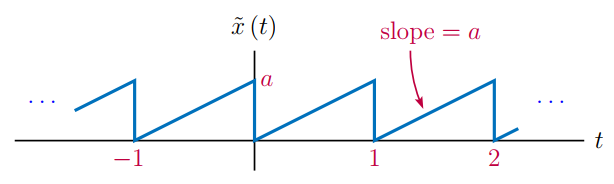

EFS coefficients are

$\textrm{Re}\left\{c_{k}\right\}=
  \left\{ 
  \begin{array}{c l}
  \frac{a}{2}, & k=0 \\
  0, & k\ne 0
  \end{array}
  \right.
$    and   $\textrm{Im}\left\{c_{k}\right\}=
  \left\{ 
  \begin{array}{c l}
  0, & k = 0 \\
  \frac{a}{2\pi k}, & k \ne 0
  \end{array}
  \right.
$                    (3.79)

Finite-harmonic approximation

        
$$\hat{x}(t)=\sum_{k=-M}^{M} c_{k}\,e^{jk\omega_{0}t}$$


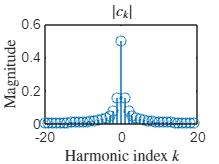

a = 1; % Slope of each period
M =      5; % Number of harmonics used in reconstruction
%
k = [-20:20]+0.001;  % Vector of harmonic indices (avoid division by zero)
% Compute the EFS coefficients
c = a*(-exp(-j*2*pi*k)./(j*2*pi*k)+(exp(-j*2*pi*k)-1)./(4*pi*pi*k.*k));
% Graph the magnitude and the phase of the line spectrum
stem(k,abs(c));
axis([-20,20,0,0.6]);
set(0,'defaultTextInterpreter','latex');
xlabel('Harmonic index $k$');
ylabel('Magnitude');
title('$|c_{k}|$');

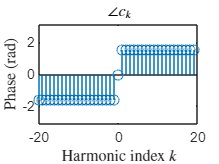

stem(k,angle(c));
axis([-20,20,-pi,pi]);
xlabel('Harmonic index $k$');
ylabel('Phase (rad)');
title('$\angle c_{k}$');

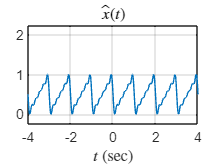

% Approximate the signal using EFS terms
t = [-4:0.01:4];
xhat = zeros(size(t));
for kk = -M:M
  xhat = xhat+c(kk+21)*exp(j*2*pi*kk*t);
end
xhat = real(xhat);
plot(t,xhat); grid;
axis([-4,4,-0.25,2.25]);
xlabel('$t$ (sec)');
title('$\hat{x}(t)$');

set(0,'defaultTextInterpreter','tex');